Ein Fehler ist aufgetreten: To assign to or create a variable in a table, the number of rows must match the height of the table.


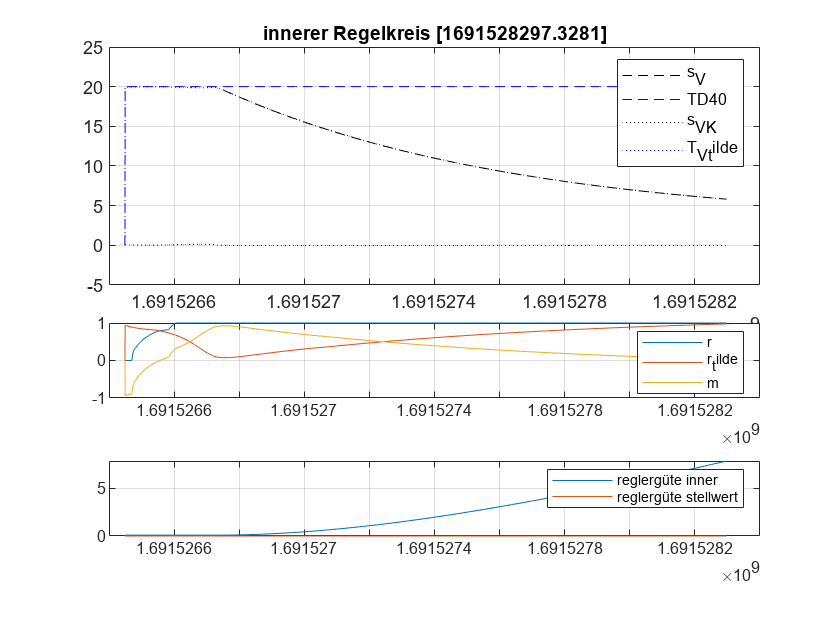

clear 

while true
    clf
    tic
    file= "../data.h5";
    table_aktualisiert = true;
    try
        info = h5info(file,'/');
        temp = table();
            for i = 1:length(info.Groups.Datasets)
                name = info.Groups.Datasets(i).Name;
                path = '/States/' + string(name);
        
                temp = addvars(temp, h5read(file,path), 'NewVariableNames', name);
            end
    catch exception
        fprintf('Ein Fehler ist aufgetreten: %s\n', exception.message);
        table_aktualisiert = false;
    end
    if table_aktualisiert
        p = temp;
    end
   
    subplot(4,1,[1 2])
    plot(p.time,p.s_V,'k','LineStyle','--')
    hold on
    plot(p.time,p.("T_D4[0]"),'b','LineStyle','--')
    plot(p.time,p.s_V_K,'k','LineStyle',':')
    plot(p.time,p.T_V_tilde,'b','LineStyle',':')
    legend({'s_V','TD40','s_V_K','T_V_tilde'})
    title('innerer Regelkreis ['+ string(p.time(end))+']')
    grid on
    subplot(4,1,3)
    plot(p.time,p.r)
    hold on
    plot(p.time,p.r_tilde)
    plot(p.time,p.m)
    legend({'r','r_tilde','m'})
    grid on
    subplot(4,1,4)
    plot(p.time,p.("güte_M"))
    hold on
    plot(p.time,p.("güte_r"))
    grid on
    legend({'reglergüte inner','reglergüte stellwert'})
    hold off


    drawnow


%     subplot(12,1,4)
%     subplot(12,1,[5 6])
%     subplot(12,1,7)
%     subplot(12,1,8)
%     subplot(12,1,[9 10])
%     subplot(12,1,[11 12])

  
    
    
    
    
    pause(1)
    
end